## Using a Trained Model In Matlab

First you must specify the path to your Transistor-Neural-Network-Modeler repository

pathToRepository = "C:/Users/Alex Prucka/IdeaProjects/Transistor-Neural-Network-Modeler/";

The path to the Matlab NNModel class is added to the classpath, and the path to the pmos1 model file is specified

modelPath = pathToRepository + "src/test/resources/pmos1.bin";
classPath = pathToRepository + "src\main\Matlab";
addpath(classPath)

A NNModel object is created, and the properties of the model are then printed, which contain the input and output column labels

model = NNModel(modelPath);
model.properties


ans =

  java.lang.String[]:

    'Input Columns: '
    'M0:gmoverid'
    'M0:fug'
    'Output Columns: '
    'L'
    'id/w'



Then the input and output data used to train the model is read from a csv file to the csvData variable

csvFile = pathToRepository + "src\test\resources\simDataPmos.csv";
csvData = dlmread(csvFile, ",", 0, 0);

Here you can select two indexs, where each index value samples a different transistor length to run through the created model

index1 = 13000

index1 = 13000

index2 = 6000

index2 = 6000

data1 = csvData(csvData(:,3)==csvData(index1,3),:);
data2 = csvData(csvData(:,3)==csvData(index2,3),:);

The output from the NNModel for both sizes is then saved

results = model.useModel(data1(:,1:2));
results2 = model.useModel(data2(:,1:2));

The data is then plotted for id/w vs gm/id from both the simulated data and the model output

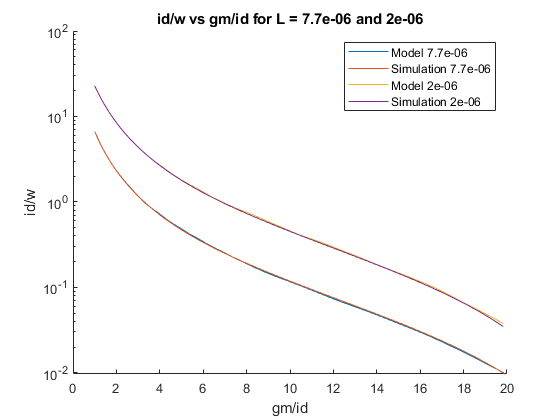

figure
hold on
plot(data1(:,1),results(:,2))
plot(data1(:,1),data1(:,4))
plot(data2(:,1),results2(:,2))
plot(data2(:,1),data2(:,4))
title("id/w vs gm/id for L = "+csvData(index1,3)+" and "+csvData(index2,3))
set(gca, 'YScale', 'log')
xlabel("gm/id")
ylabel("id/w")
legend("Model "+csvData(index1,3),"Simulation "+csvData(index1,3), "Model "+csvData(index2,3), "Simulation "+csvData(index2,3))
hold off

Now length vs gm/id are compared between the two

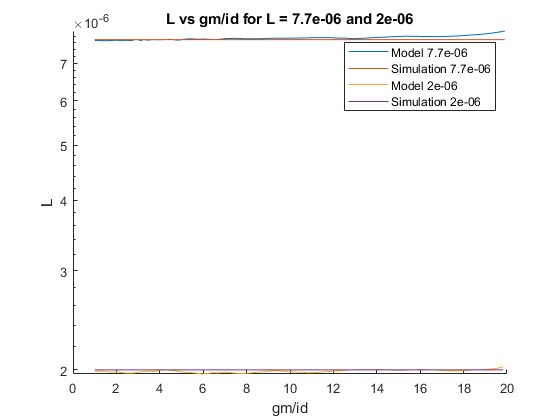

figure
hold on
plot(data1(:,1),results(:,1))
plot(data1(:,1),data1(:,3))
plot(data2(:,1),results2(:,1))
plot(data2(:,1),data2(:,3))
title("L vs gm/id for L = "+csvData(index1,3)+" and "+csvData(index2,3))
set(gca, 'YScale', 'log')
xlabel("gm/id")
ylabel("L")
legend("Model "+csvData(index1,3),"Simulation "+csvData(index1,3), "Model "+csvData(index2,3), "Simulation "+csvData(index2,3))
hold off

Some of the charts and examples which take longer to run do not integrate as well into the live script, and thus they are housed in the JavaInMatlab.m file where you can run them